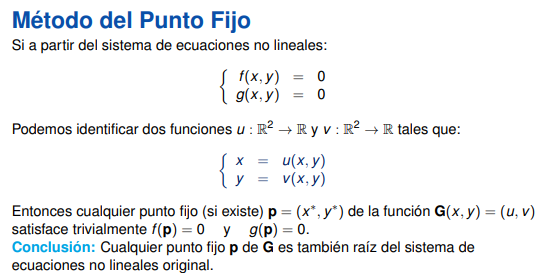

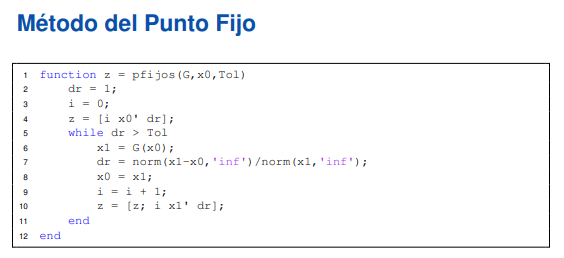

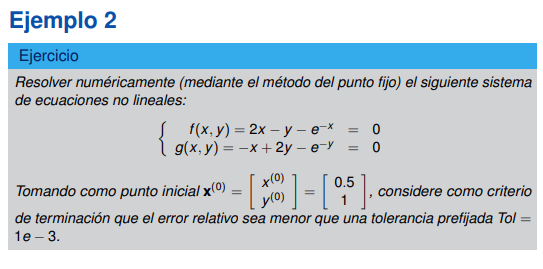

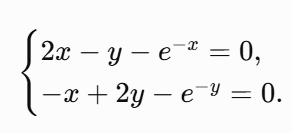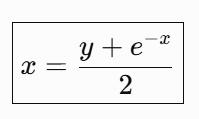

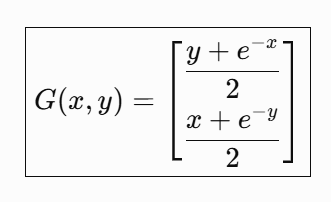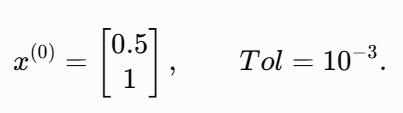

G = @(x) [(x(2)+exp(-x(1)))/2; ...      % Define la primera función de punto fijo
    (x(1)+exp(-x(2)))/2];         % Define la segunda función de punto fijo

x0 = [0.5; 1];                          % Define el punto inicial

Tol = 1e-3;                             % Define la tolerancia

z = pfijos(G,x0,Tol)                    % Ejecuta el método del punto fijo

z =          0    0.5000    1.0000    1.0000
    1.0000    0.8033    0.4339    0.7047
    2.0000    0.4409    0.7256    0.4994
    3.0000    0.6845    0.4625    0.3844
    4.0000    0.4834    0.6571    0.3061
    5.0000    0.6369    0.5009    0.2453
    6.0000    0.5149    0.6215    0.1963
    7.0000    0.6095    0.5260    0.1566
    8.0000    0.5348    0.6002    0.1244
    9.0000    0.5930    0.5418    0.0986
   10.0000    0.5472    0.5874    0.0780
   11.0000    0.5830    0.5515    0.0615
   12.0000    0.5549    0.5795    0.0485
   13.0000    0.5768    0.5575    0.0381
   14.0000    0.5596    0.5747    0.0300


function z = pfijos(G,x0,Tol)            % Define la función del método de punto fijo

dr = 1;                              % Inicializa el error relativo

i = 0;                               % Inicializa el contador de iteraciones

z = [i x0' dr];                      % Guarda la iteración inicial, x, y y el error

while dr > Tol                       % Repite mientras el error sea mayor que la tolerancia

    x1 = G(x0);                      % Calcula la nueva aproximación

    dr = norm(x1-x0,'inf')/norm(x1,'inf'); % Calcula el error relativo con norma infinito

    x0 = x1;                         % Actualiza el punto para la siguiente iteración

    i = i + 1;                       % Incrementa el contador de iteraciones

    z = [z; i x1' dr];               % Guarda la iteración, x, y y el error

end                                  % Finaliza el ciclo while

end                                      % Finaliza la función
z(end-5:end,:)     % Muestra las últimas 6 filas de la matriz z

ans =    23.0000    0.5680    0.5663    0.0034
   24.0000    0.5665    0.5678    0.0026
   25.0000    0.5677    0.5666    0.0021
   26.0000    0.5667    0.5675    0.0016
   27.0000    0.5675    0.5668    0.0013
   28.0000    0.5669    0.5674    0.0010


z(end,:)             % Muestra únicamente la iteración final

ans =    28.0000    0.5669    0.5674    0.0010


format long g        % Muestra más cifras
disp(z)              % Muestra la matriz

                         0                       0.5                         1                         1
                         1         0.803265329856317         0.433939720585721         0.704699005888294
                         2         0.440901935136891         0.725608321145043         0.499392556782701
                         3         0.684532062514729         0.462465984405498         0.384411996383124
                         4         0.483396075946246         0.657130445131238         0.306082282534198
                         5         0.636907982912813          0.50086633685215         0.245348013325937
                         6         0.514895840644096         0.621456705154943         0.196332489868779
                         7         0.609509769145787         0.526028611141373          0.15656532322248
                         8         0.534822956438988         0.600228482955841         0.124430637378288
                         9         0.593000735628306   